# Exercise 2: Setup Estimation Filter to Track A Single Piece of Space Debris

**Exercise 2a: State Estimation Using Default initcvekf - Where will the debris be in one time step?**

First, let's test how the default constant velocity extended kalman filter performs on our dataset for a single piece of space debris.

We can clear our workspace and command window and also close all open figures with the commands below:

clear; clc; close all; addpath('../HelperFunctions/')

Let's load in our truth and detection data from the previous example:

S = load('SpaceDebrisLEO_1Target.mat');
truthPosition = S.truthPos;       % Truth Position - where the target actually is
detectionPosition = S.detPos;     % Detection Position - where the target was detected
time = S.time;                    % Time vector, maps to each detection
objectDetection = S.objDet;       % Object Detection as an "object detection object"
speed = S.speed;                  % Known speed of debris
initialDetection = objectDetection{1}; % Object Detection format of detection
detectionMeasurementNoise = initialDetection.MeasurementNoise; % Measurment Noise associated with detections

Now, let's define a filter.

Coding Directions:

Please create a variable 'filter' that holds the default Constant Velocity Extended Kalman Filter (EKF) estimation filter. Define the estimation filter using a "initcvekf" filter. This filter initialization function requires a detection as input. Pass the "initialDetection" to "initcvekf".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc initcvekf" in the Command Window to find the documentation page for this function
filter = initcvekf(initialDetection);
% This filter runs with default inputs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function filter = initFilter(detection)
filter = initcvekf(detection); % <____

% State Cov
% Proc Noise

end

**Plot Detections, Predictions, and Corrections**

Loop through the detection data via the time vector to plot detections, predictions, and corrections as the target moves through the space.

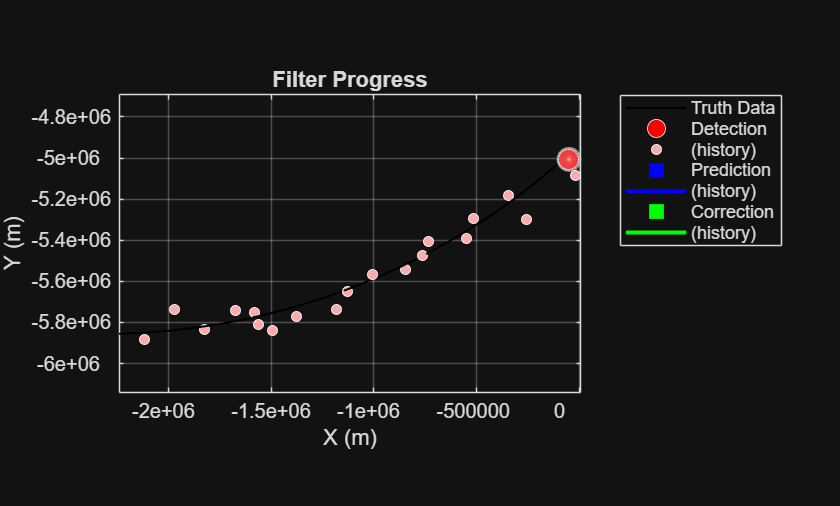

%mahalanobisDist = helperRunDataLoop_CV(detectionPosition,truthPosition,filter,time,objectDetection{1}.MeasurementNoise);
tp = theaterPlot();

% Create Plotters
trajPlotter = trajectoryPlotter(tp,'DisplayName','Truth Data','LineWidth',1,'LineStyle','-','Color','k');
detPlotter = detectionPlotter(tp,'HistoryDepth',1e3,'DisplayName','Detection','MarkerSize',10,'MarkerFaceColor','r');
predPlotter = trackPlotter(tp,'HistoryDepth',1e3,'DisplayName','Prediction','MarkerSize',10,'MarkerFaceColor','b','MarkerEdgeColor','b','ConnectHistory','on');
corrPlotter = trackPlotter(tp,'HistoryDepth',1e3,'DisplayName','Correction','MarkerSize',10,'MarkerFaceColor','g','MarkerEdgeColor','g','ConnectHistory','on');

% Plot Truth As Trajectory
plotTrajectory(trajPlotter,{truthPosition'})
grid on, box on; legend(gca,'Location','northwest')

% Plot Detections in a "as sensor detects target" fashion
for n = 2:length(time)
    deltaT = time(n)-time(n-1);
    % Plot Position of Current Detection iteration 
    plotDetection(detPlotter,detectionPosition(:,n)',detectionMeasurementNoise) % Adds ellipses on Detections

    % Make state prediction using predict method of the filter
    predict(filter,deltaT);

    filter.MeasurementNoise = detectionMeasurementNoise;

    % Log the Distance Value -> dn = r'/S*r + log(|S|)
    logDist(n) = distance(filter, detectionPosition(:,n));

    % Correct estimate using detections and the correct method of the filter
    correct(filter, detectionPosition(:,n));
    
    a = struct('State',filter.State,'StateCovariance',filter.StateCovariance); % Update Plotter
    [b, b2] = getTrackPositions(a,'constvel'); % Update Plotter

    % Pull out position only from prediction and correction, for plotting
    % Constant Velocity
    % pstatesPos = pstates(:,[1 3 5]); posPCov = pCov([1 3 5],[1 3 5],:);
    % cstatesPos = cstates(:,[1 3 5]); posCCov = cCov([1 3 5],[1 3 5],:);
    % 
    % % Plot Prediction and Correction
    % plotTrack(predPlotter,pstatesPos(n,:),posPCov(:,:,n),string(1)) % Plot Prediction
    % plotTrack(corrPlotter,cstatesPos(n,:),posCCov(:,:,n),string(1)) % Plot Correction

    % Draw Detections and Tracks During Each Loop
    drawnow
end

% See Algorithm Defintiion here: https://www.mathworks.com/help/fusion/ref/trackingekf.distance.html?s_tid=srchtitle_support_results_4_distance#mw_b0a1e319-2a1f-4486-b99c-f004de782d15


% Add Title and Rotate to 2D view
title('Filter Progress'); hold on; grid on; axis equal; % Add Title
view([0 90.00]) % Rotate to 2D view


% Calculate Mahalanobis Distance - Position-Only (posnees) form:
% Corrected versus Truth
mahalanobisDist = helperCalcMahalanobisDist_CV(truthPosition,cstates,cCov,time);

Unrecognized function or variable 'cstates'.


figure;
plot(logDist); hold on; plot(mahalanobisDist); 
title('Distance vs. Mahalanobis Distance')
legend(['Distance','Mahalanobis Distance'],"Location", 'northwest')

**Plot the Mahalanobis Distance**

Plot the Mahalanobis Distance comparing the corrected state to the truth trajectory as a measure of how well the filter is tuned.

mahalanobisDistanceDefault  = helperPlotMahalanobisDist_FirstPlot(mahalanobisDist);

**Exercise 2b: Improve State Estimation by Adjusting Filter Settings **

**With the default settings, we see that our predicted and corrected values don't match our data. What do we do now?**

Let's adjust the filter to better match our dataset.

**Information Provided by Tracking Engineer:**

knownVelo = 7.5e3; % m/s - Estimate of Space Debris Velocity
initialStateCovariance = blkdiag(detectionMeasurementNoise(1)^2,knownVelo^2,...
    detectionMeasurementNoise(1)^2,knownVelo^2,...
    detectionMeasurementNoise(1)^2,knownVelo^2);
processNoise = blkdiag(1,1,1)*10^3;

Setup a new tracker:

filter = initcvekf(initialDetection);

**Update Filter Settings to Improve State Estimation**

There are three (3) parameters of the filter to change, directions are enumerated a though d below.

Coding Directions: 

a) Assign the initial **state covariance** matrix to the current state covariance stored within the filter. This can be done using the value in the variable "initialStateCovariance" above. You can access this property using "filter.StateCovariance". 

b)  Assign the **process noise** given to you by the tracking engineer to the process noise of the filter.  This can be done using the value stored in the variable "processNoise" above.  You can access this property using "filter.ProcessNoise".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc trackingEKF" in the Command Window to find the documentation
% page for this function and look for the "State" Property 
filter.StateCovariance = initialStateCovariance; % Task A
filter.ProcessNoise = processNoise; % Task B
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Print out the new initial state estimate (this can optionally be done for each of the parameters we just updated):

disp(filter.State)

**Plot Detections, Predictions, and Corrections for the Updated Filter**

Loop through the detection data via the time vector to plot detections, predictions, and corrections as the target moves through the space.

mahalanobisDist = helperRunDataLoop_CV(detectionPosition,truthPosition,filter,time,objectDetection{1}.MeasurementNoise);

**Plot the Mahalanobis Distance**

Plot the Mahalanobis Distance comparing the corrected state to the truth trajectory as a measure of how well the filter is tuned.

helperPlotMahalanobisDist(mahalanobisDist,mahalanobisDistanceDefault);

**Exercise 2c: Leverage a Tuned Filter to Estimate the State**

In our case, our dataset is made from simulated truth positions of our targets, which can be leveraged as truth data.  This makes filter tuning possible. For this exercise, we have performed the tuning for you.

Coding Directions

Leverage the "tunedInitFcn_CV" function to initialize the filter. This can be accomplished by passing the "initialDetection" variable to the function "tunedInitFcn_CV" and storing the output in the variable "filter".

The "tunedInitFcn_CV" function was created by leveraging the "trackingFilterTuner" function and our truth data to tune the parameters of our "initcvekf" filter.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc trackingFilterTuner" in the Command Window to find the documentation
% page for this function and look for the "Customize Tunable Properties and
% Tune Tracking Filter" Example
filter = tunedInitFcn_CV(initialDetection);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Plot Detections, Predictions, and Corrections for the Previously Tuned Filter Using the Output of the Filter Tuner**

Loop through the detection data via the time vector to plot detections, predictions, and corrections as the target moves through the space.

mahalanobisDist = helperRunDataLoop_CV(detectionPosition,truthPosition,filter,time,objectDetection{1}.MeasurementNoise);

**Plot the Mahalanobis Distance**

Plot the Mahalanobis Distance comparing the corrected state to the truth trajectory as a measure of how well the filter is tuned.

helperPlotMahalanobisDist(mahalanobisDist,mahalanobisDistanceDefault);

# **Takeaways**

Once we have setup our estimation filter to match the motion of the targets within our scenario, we see that our predicted and corrected locations are close to the detections AND that our Mahalanobis distances are around 2 Standard Deviations. In general, it is critical that the estimation filter is adjusted to match the expected dynamics of the targets that you are tracking.

**BONUS - Tune Filter Using "tuneFilter" Function**

In Exercise 2c, we performed the tuning for you. If you are interesting in how this was done, please check the Live Script "TuneFilter_CV.mlx" in the Soluions folder.

function plotter = createPlotter()


end